# Practico con utilitario 1

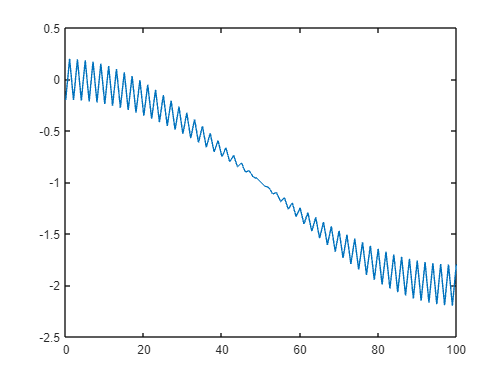

[n,senial_t] = senial(748695);
plot(n,senial_t);

## Tranformada de Fourier de la señal de tiempo discreto (TFTD)

La TFTD de una señal de soporte finito; en este caso de k muestras, se puede calcular como:

    
$$X\left(s\right)=\sum_{n=0}^k x\left\lbrack n\right\rbrack \times e^{-\mathrm{j2}\pi \mathrm{sn}}$$


donde ***k*** es el numero de muestras de la señal y ***s ***es la frecuencia normalizada y es un numero real.

$X\left(s\right)$ es una funcion periodica de periodo 1, por lo que solo la voy a graficar entre $s=-\frac{1}{2}$ y $s=\frac{1}{2}$ , ya que mas alla de eso seria redundante. Tambien como s es un numero real, para calcular la** TFTD** numericamente voy a usar valores discretos de ***s*** con un paso $\mathrm{ds}=0\ldotp 001$ 

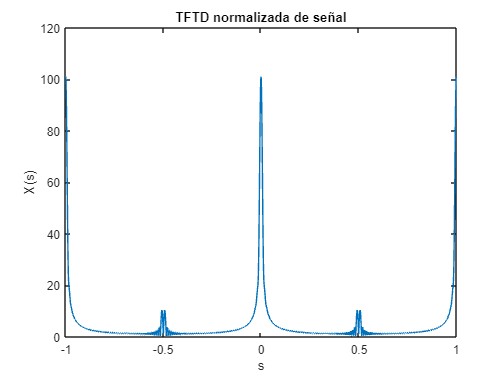

ds = 0.0001; s = -1:ds:1; senial_TFTD = zeros(1,length(s));

for i = 1:length(senial_TFTD)
    senial_TFTD(i) = sum(senial_t.*exp(-1j*2*pi*s(i)*n));
end

figure
plot(s,abs(senial_TFTD));
title('TFTD normalizada de señal')
xlabel('s')
ylabel('X(s)')